# Import and plotting a structure

## Import a structure

This is how we import any .gro | .pdb | .xyz file

atom=import_atom('96spc_hex_ice_h.gro');

Found .gro file
.gro file imported
Elapsed time is 0.016942 seconds.
Looking up bonds
Calculating the distance matrix


ans = 1×1 cell array
    {'H'}

ans = 1×1 cell array
    {'O'}

ans =    288

Composition info:


composition = struct with fields:
     resnames: {'SOL'}
    nresidues: 96
       natoms: 288

Atom_types = 1×3 cell array
    {'HW1'}    {'HW2'}    {'OW'}

Atom_numbers =     96    96    96


The box dimensions are:


Box_dim =   13.521200000000000  15.612900000000000  14.719999999999999


The cell dimensions are:


Cell =   13.521200000000000  15.612900000000000  14.719999999999999  90.000000000000000  90.000000000000000  90.000000000000000


..or you could try these commands specific for each filetype

% atom=import_atom_gro('filename.gro');
% atom=import_atom_pdb('filename.pdb');
% atom=import_atom_xyz('filename.xyz'); % any info regarding box size? If not add it manually to the Box_dim 1x3 (1x9 for triclinic) vector

## Now let's plot the imported simulation box

The atom scripts comes with a simple plot function called plot_atom, which can display and rotate a simulation cell in 3D.

show_atom(atom,Box_dim,'halfvdw','box'); % 'axis' argument is optional

Choose between these representations:
ballstick licorice smallvdw halfvdw vdw contour crystal ionic polyhedra lines labels charge index


rmaxlong =    2.250000000000000

Calculating the distance matrix


ans = 1×1 cell array
    {'H'}

ans = 1×1 cell array
    {'O'}

ans =    288

Used this rmaxlong and distance_factor:


rmaxlong =    2.250000000000000

distance_factor =    0.600000000000000

Elapsed time is 0.254677 seconds.
Drawing the atoms
Elapsed time is 0.068797 seconds.
Elapsed time is 0.000056 seconds.


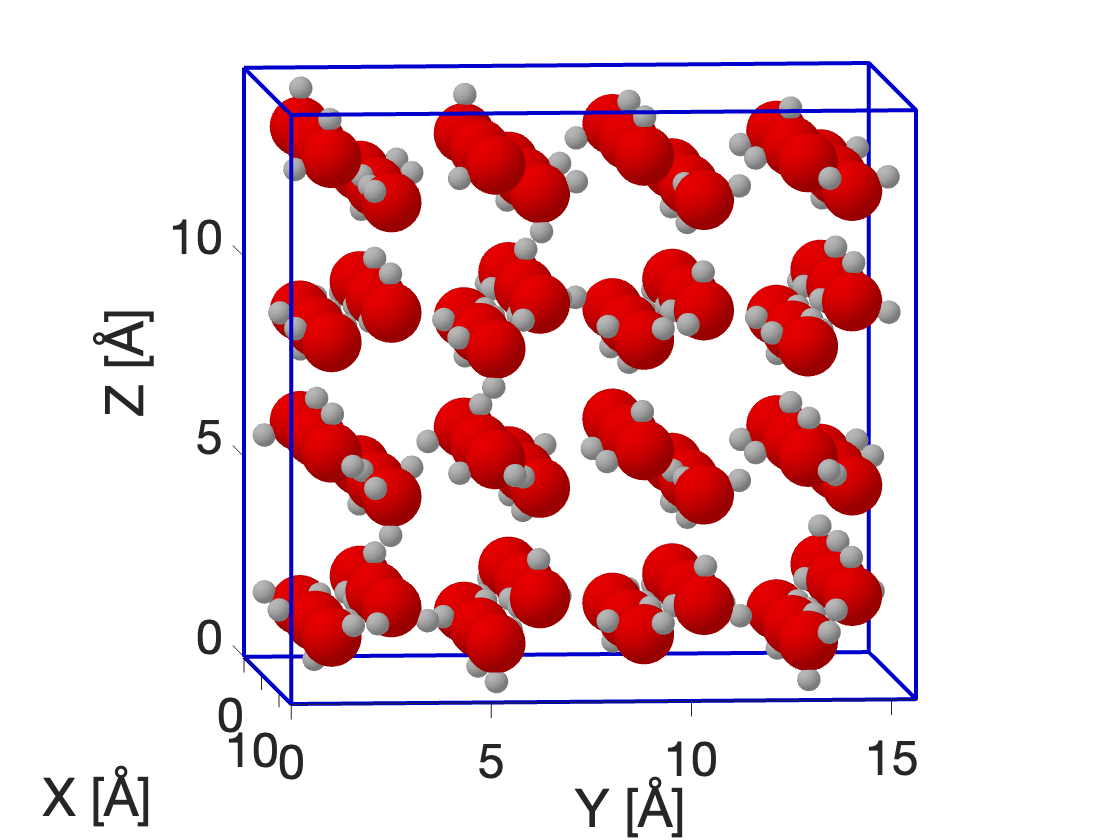

view(85,5); % change the default view

However, you could also use VMD if the path in the function PATH2VMD() is set correctly. Note that VMD will lock the matlab editor/parser as long a its open, but can be closed by issuing 'exit' in the command window. Anyway,to run VMD try invoking:

vmd(atom,Box_dim);

or plot the file direclty by issuing something like:

% vmd('96spc_hex_ice_h.gro');